# Season 2: State-Space Modeling and Linearization

**Learning Outcomes:**

- Convert ODEs to state-space representation

- Create and manipulate state-space and transfer function models

- Linearize nonlinear systems using Jacobian

- Analyze system responses (step, impulse, initial condition)

- Apply Laplace transforms for system analysis

- Perform continuous-discrete conversions

**Prerequisites:** Season 1 (Mathematical Foundations)

**MATLAB Version:** R2025b

**Toolboxes Required:** Control System Toolbox, Symbolic Math Toolbox

close all; clear; clc;
rng(0);

## Section 2.1: From Differential Equations to State-Space

**Mathematical Background**

State-space representation for linear time-invariant (LTI) systems:


$$\dot{x} = Ax + Bu$$



$$y = Cx + Du$$


where:

- x: state vector (n×1)

- u: input vector (m×1)

- y: output vector (p×1)

- A: state matrix (n×n)

- B: input matrix (n×m)

- C: output matrix (p×n)

- D: feedthrough matrix (p×m)

Example: Mass-Spring-Damper System

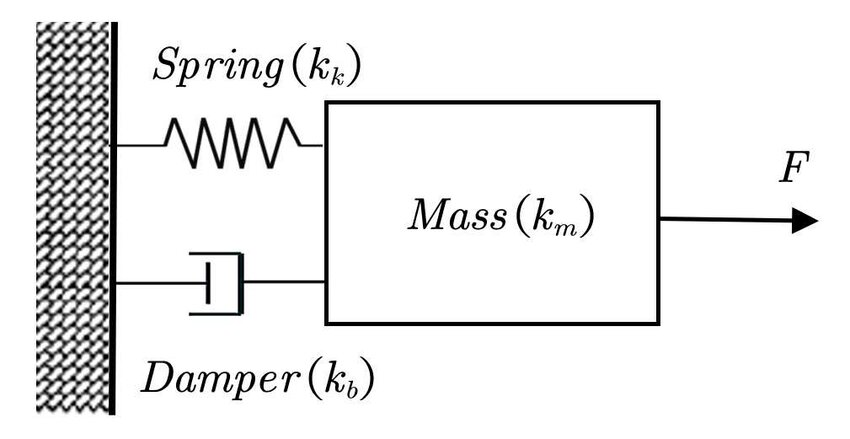

Equation: m*ẍ + c*ẋ + k*x = F

Let x₁ = x (position), x₂ = ẋ (velocity)

Then: ẋ₁ = x₂

ẋ₂ = -(k/m)x₁ - (c/m)x₂ + (1/m)F

m = 1;    % mass (kg)
c = 0.5;  % damping (N·s/m)
k = 2;    % spring constant (N/m)

A_msd = [0, 1;
         -k/m, -c/m];
B_msd = [0; 1/m];
C_msd = [1, 0];  % Measure position
D_msd = 0;

fprintf('Mass-Spring-Damper System:\n');

Mass-Spring-Damper System:


fprintf('m = %.2f kg, c = %.2f N·s/m, k = %.2f N/m\n\n', m, c, k);

m = 1.00 kg, c = 0.50 N·s/m, k = 2.00 N/m



fprintf('State-space matrices:\n');

State-space matrices:


fprintf('A =\n'); disp(A_msd);

A =
         0    1.0000
   -2.0000   -0.5000



fprintf('B =\n'); disp(B_msd);

B =
     0
     1



fprintf('C =\n'); disp(C_msd);

C =
     1     0



fprintf('D = %.1f\n\n', D_msd);

D = 0.0



Create state-space object

sys_msd = ss(A_msd, B_msd, C_msd, D_msd);
fprintf('State-space system object:\n');

State-space system object:


disp(sys_msd);

  ss with properties:

                A: [2×2 double]
                B: [2×1 double]
                C: [1 0]
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



## Section 2.2: State-Space and Transfer Function Objects

**Concept Overview**

MATLAB provides powerful objects for system representation:

- `ss()` - state-space model

- `tf()` - transfer function model

- Conversion: `ss2tf()`, `tf2ss()`

Define a simple second-order system

A = [0 1; -2 -3];
B = [0; 1];
C = [1 0];
D = 0;

sys_ss = ss(A, B, C, D); % State-space representation


% Convert to transfer function
[num, den] = ss2tf(A, B, C, D);

% Extract numerator and denominator
fprintf('Numerator coefficients:\n'); disp(num);

Numerator coefficients:
     0     0     1



fprintf('Denominator coefficients:\n'); disp(den);

Denominator coefficients:
     1     3     2




fprintf('Transfer function representation:\n');

Transfer function representation:


sys_tf = tf(num, den)


sys_tf =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


### Convert transfer function back to state-space

Note: Multiple state-space realizations exist for one transfer function

[A_back, B_back, C_back, D_back] = tf2ss(num, den);

fprintf('Convert back to state-space (controllable canonical form):\n');

Convert back to state-space (controllable canonical form):


fprintf('A =\n'); disp(A_back);

A =
    -3    -2
     1     0



fprintf('B =\n'); disp(B_back);

B =
     1
     0



fprintf('C =\n'); disp(C_back);

C =
     0     1



fprintf('D = %.1f\n\n', D_back);

D = 0.0



Verify they represent the same system by checking transfer functions

sys_ss_back = ss(A_back, B_back, C_back, D_back);
fprintf('Transfer function from reconstructed state-space:\n');

Transfer function from reconstructed state-space:


sys_tf_back = tf(sys_ss_back)


sys_tf_back =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


## Section 2.3: System Response Analysis

**Concept Overview**

Key system responses:

- Step response: output when u(t) = 1 for t ≥ 0

- Impulse response: output when u(t) = δ(t)

- Initial condition response: output with u(t) = 0, x(0) ≠ 0

- General response: `lsim()` for arbitrary inputs

Use the mass-spring-damper system

Analyzing Mass-Spring-Damper System

### Step response

figure('Name', 'System Responses - Mass-Spring-Damper');
subplot(2,2,1);
step(sys_msd, 10);
grid on;
title('Step Response');
ylabel('Position (m)');

### Impulse response

subplot(2,2,2);
impulse(sys_msd, 10);
grid on;
title('Impulse Response');
ylabel('Position (m)');

### Initial condition response

x0 = [1; 0];  % Initial displacement, zero velocity
subplot(2,2,3);
initial(sys_msd, x0, 10);
grid on;
title('Initial Condition Response');
ylabel('Position (m)');

### Custom input using lsim

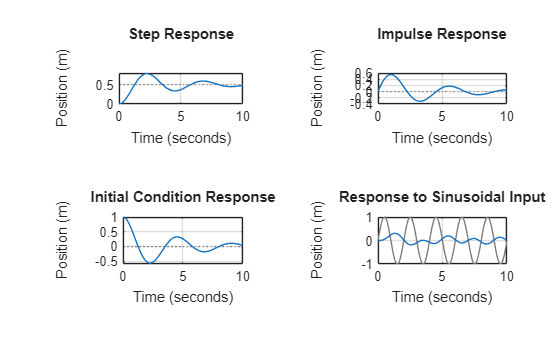

t = linspace(0, 10, 200);
u = sin(2*pi*0.5*t);  % Sinusoidal input at 0.5 Hz

subplot(2,2,4);
lsim(sys_msd, u, t);
grid on;
title('Response to Sinusoidal Input');
ylabel('Position (m)');

### Get numerical data from step response

[y_step, t_step, x_step] = step(sys_msd, 10);

% Performance metrics
info = stepinfo(sys_msd);
fprintf('Step Response Performance:\n');

Step Response Performance:


fprintf('  Rise Time: %.4f s\n', info.RiseTime); % by using info.(property) we are extracting the data stored in stepinfo struct, use "help struct" in matlab console to read more.

  Rise Time: 0.8441 s


fprintf('  Settling Time: %.4f s\n', info.SettlingTime);

  Settling Time: 14.2451 s


fprintf('  Overshoot: %.2f%%\n', info.Overshoot);

  Overshoot: 56.75%


fprintf('  Peak: %.4f\n', info.Peak);

  Peak: 0.7838


fprintf('  Peak Time: %.4f s\n\n', info.PeakTime);

  Peak Time: 2.2105 s



## Section 2.4: State Transition and Matrix Exponential

**Mathematical Background**

Solution to $\dot{x} = Ax$ with initial condition $x(0) = x_0$:


$$x(t) = e^{At}x_0$$


where $e^{At}$ is the state transition matrix.

For systems with input:


$$x(t) = e^{At}x_0 + \int_0^t e^{A(t-\tau)}Bu(\tau)d\tau$$


A = [0 1; -2 -3];
x0 = [1; 0];

fprintf('System matrix A:\n');

System matrix A:


disp(A);

     0     1
    -2    -3



fprintf('Initial state x(0):\n');

Initial state x(0):


disp(x0');

     1     0



### Compute state at different times using expm

t_values = [0, 0.5, 1.0, 2.0, 5.0];

fprintf('\nState evolution using x(t) = exp(At)*x(0):\n');


State evolution using x(t) = exp(At)*x(0):


fprintf('Time\t\tx₁(t)\t\tx₂(t)\n');

Time		x₁(t)		x₂(t)


fprintf('----\t\t------\t\t------\n');

----		------		------



for t_val = t_values
    Phi_t = expm(A * t_val);  % State transition matrix
    x_t = Phi_t * x0;
    fprintf('%.2f\t\t%.4f\t\t%.4f\n', t_val, x_t(1), x_t(2));
end

0.00		1.0000		0.0000
0.50		0.8452		-0.4773
1.00		0.6004		-0.4651
2.00		0.2524		-0.2340
5.00		0.0134		-0.0134


Compare with numerical integration using ode45

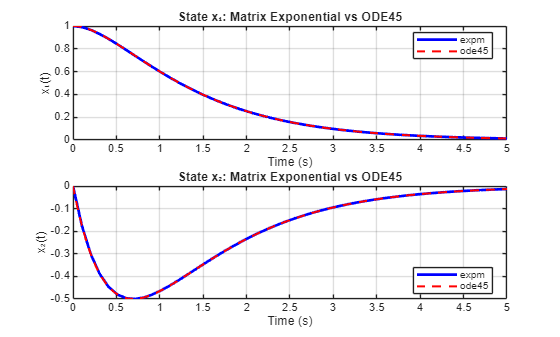

[t_ode, x_ode] = ode45(@(t,x) A*x, [0 5], x0);

figure('Name', 'State Transition Comparison');
t_expm = linspace(0, 5, 50);
x_expm = zeros(2, length(t_expm));

for i = 1:length(t_expm)
    x_expm(:,i) = expm(A * t_expm(i)) * x0;
end

subplot(2,1,1);
plot(t_expm, x_expm(1,:), 'b-', 'LineWidth', 2, 'DisplayName', 'expm');
hold on;
plot(t_ode, x_ode(:,1), 'r--', 'LineWidth', 1.5, 'DisplayName', 'ode45');
grid on;
xlabel('Time (s)');
ylabel('x₁(t)');
title('State x₁: Matrix Exponential vs ODE45');
legend('Location', 'best');

subplot(2,1,2);
plot(t_expm, x_expm(2,:), 'b-', 'LineWidth', 2, 'DisplayName', 'expm');
hold on;
plot(t_ode, x_ode(:,2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'ode45');
grid on;
xlabel('Time (s)');
ylabel('x₂(t)');
title('State x₂: Matrix Exponential vs ODE45');
legend('Location', 'best');

### Solving using "Solve ODE" task:

%% HELPER FUNCTIONS
function dydt = ode_linear(t, y)
    A = [0 1; -2 -3];
    dydt = A * y;
end

figure;

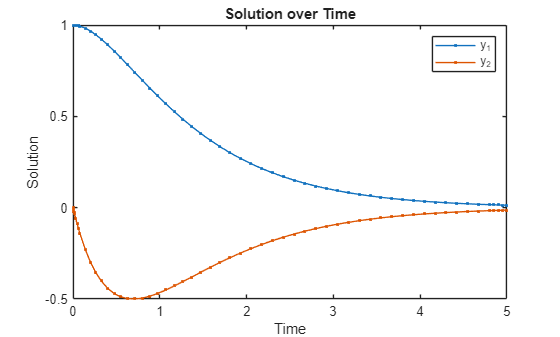

% Define ODE problem and specify solver options
odeObj = ode(ODEFcn = @ode_linear, ...
    InitialValue = [1; 0]);

% Solve ODE problem
solData = solve(odeObj,0,5);

% Plot solution over time
plot(solData.Time,solData.Solution,".-");

ylabel("Solution")
xlabel("Time")
title("Solution over Time")
legend("y_1","y_2")
clear odeObj

## Section 2.5: Laplace Transforms

**Mathematical Background**

Laplace transform converts time-domain to frequency-domain:


$$\mathcal{L}\{f(t)\} = F(s) = \int_0^{\infty} f(t)e^{-st}dt$$


Inverse Laplace transform:


$$\mathcal{L}^{-1}\{F(s)\} = f(t)$$


### Basic Laplace transforms

syms y positive
syms t s a w

f1 = exp(-a*t);
F1 = laplace(f1);

fprintf('Time-domain: f(t) = exp(-at)\n');

Time-domain: f(t) = exp(-at)


fprintf('Laplace transform: F(s) = '); disp(F1);

Laplace transform: F(s) = 

$$\frac{1}{a+s}$$

### Laplace transform with different variables

F2 = laplace(f1, y);
fprintf('Laplace transform (variable y): F(y) = ');

Laplace transform (variable y): F(y) = 

disp(F2);

$$\frac{1}{a+y}$$

### Common Laplace transforms

% Define time-domain functions
time_funcs = {
    1
    t
    exp(-a*t)
    sin(w*t)
    cos(w*t)
    t^2
    exp(-a*t)*sin(w*t)
};

% Initialize cell arrays for results
laplace_results = cell(size(time_funcs));
invlaplace_results = cell(size(time_funcs));

% Compute Laplace and inverse Laplace
for i = 1:length(time_funcs)
    f = time_funcs{i};
    F = laplace(f, t, s); % lalplace trasnform
    f_inv = ilaplace(F, s, t); % Inverse laplace transform
    laplace_results{i} = F;
    invlaplace_results{i} = f_inv;
end

% Create a table for display
T = table( ... % use 3 dots to continue the code on the next line
    time_funcs, ...
    laplace_results, ...
    invlaplace_results, ...
    'VariableNames', {'f(t)', 'Laplace F(s)', 'Inverse Laplace of F(s)'} ...
);

% Display the table
disp('Laplace and Inverse Laplace Transform Table:');

Laplace and Inverse Laplace Transform Table:


disp(T);

             f(t)                  Laplace F(s)          Inverse Laplace of F(s)
    ______________________    _______________________    _______________________

    {[                 1]}    {[1/s                ]}    {[1                 ]} 
    {[t                 ]}    {[1/s^2              ]}    {[t                 ]} 
    {[exp(-a*t)         ]}    {[1/(a + s)          ]}    {[exp(-a*t)         ]} 
    {[sin(t*w)          ]}    {[w/(s^2 + w^2)      ]}    {[sin(t*w)          ]} 
    {[cos(t*w)          ]}    {[s/(s^2 + w^2)      ]}    {[cos(t*w)          ]} 
    {[t^2               ]}    {[2/s^3              ]}    {[t^2               ]} 
    {[exp(-a*t)*sin(t*w)]}    {[w/((a + s)^2 + w^2)]}    {[exp(-a*t)*sin(t*w)]} 



Another example:

% Inverse Laplace transform
F_inv = 1 / (s + 20);
f_inv = ilaplace(F_inv);

fprintf('\nInverse Laplace Transform:\n');


Inverse Laplace Transform:


fprintf('F(s) ='); disp(F_inv);

F(s) =

$$\frac{1}{s+20}$$

fprintf('f(t) ='); disp(f_inv);

f(t) =

$${\mathrm{e}}^{-20\,t}$$

### Transfer function analysis using Laplace


$$\[
\text{System: } \ddot{x} + 3\dot{x} + 2x = u
\]
\[
\text{Transfer function: } H(s) = \frac{1}{s^2 + 3s + 2}
\]
$$


num_sym = 1;
den_sym = s^2 + 3*s + 2;
H_s = num_sym / den_sym;

fprintf('H(s) = ');

H(s) = 

disp(H_s);

$$\frac{1}{s^{2}+3\,s+2}$$

### Partial fraction expansion

[r, p, k] = residue(1, [1 3 2]);
fprintf('Partial fraction expansion:\n');

Partial fraction expansion:


fprintf('Residues: '); disp(r');

Residues:     -1     1



fprintf('Poles: '); disp(p');

Poles:     -2    -1



fprintf('Direct term: '); disp(k);

Direct term: 

## Section 2.6: Continuous-Discrete Conversion

**Concept Overview**

Digital control requires discretization:

- `c2d()` - continuous to discrete

- `d2c()` - discrete to continuous

Discretization methods:

- Zero-order hold (ZOH) - most common

- First-order hold (FOH)

- Tustin/Bilinear transformation

- Matched poles and zeros

% Continuous system
A_c = [0 1; -2 -3];
B_c = [0; 1];
C_c = [1 0];
D_c = 0;

sys_c = ss(A_c, B_c, C_c, D_c);

% Discretize with different sampling times
Ts_values = [0.1, 0.5, 1.0];

figure('Name', 'Effect of Sampling Time on Discretization');
t_cont = 0:0.01:10;
[y_cont, t_cont] = step(sys_c, t_cont);

plot(t_cont, y_cont, 'k-', 'LineWidth', 2, 'DisplayName', 'Continuous');
hold on;
grid on;

for i = 1:length(Ts_values)
    Ts = Ts_values(i);
    
    % Discretize using zero-order hold
    sys_d = c2d(sys_c, Ts, 'zoh');
    
    fprintf('\nDiscrete system (Ts = %.2f s, ZOH):\n', Ts);
    disp(sys_d);
    
    % Step response
    t_disc = 0:Ts:10;
    [y_disc, t_disc] = step(sys_d, t_disc);
    
    plot(t_disc, y_disc, 'o-', 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Discrete (Ts=%.1f)', Ts));
end


Discrete system (Ts = 0.10 s, ZOH):


  ss with properties:

                A: [2×2 double]
                B: [2×1 double]
                C: [1 0]
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0.1000
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




Discrete system (Ts = 0.50 s, ZOH):


  ss with properties:

                A: [2×2 double]
                B: [2×1 double]
                C: [1 0]
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0.5000
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




Discrete system (Ts = 1.00 s, ZOH):


  ss with properties:

                A: [2×2 double]
                B: [2×1 double]
                C: [1 0]
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 1
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



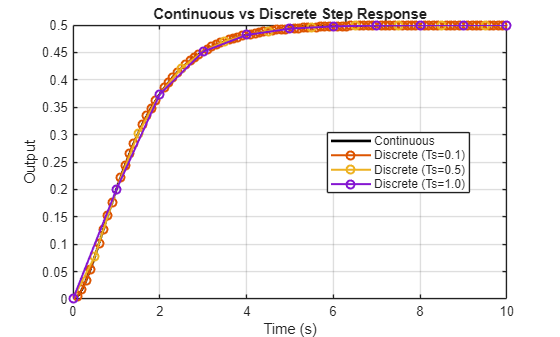


xlabel('Time (s)');
ylabel('Output');
title('Continuous vs Discrete Step Response');
legend('Location', 'best');

% Compare discretization methods
Ts = 0.1;
fprintf('\n\nComparing discretization methods (Ts = %.2f s):\n', Ts);



Comparing discretization methods (Ts = 0.10 s):



methods = {'zoh', 'foh', 'tustin', 'matched'};
method_names = {'Zero-Order Hold', 'First-Order Hold', 'Tustin', 'Matched'};

for i = 1:length(methods)
    try
        sys_d_method = c2d(sys_c, Ts, methods{i});
        fprintf('\n%s:\n', method_names{i});
        fprintf('  A_d:\n');
        disp(sys_d_method.A);
    catch
        fprintf('\n%s: Not applicable for this system\n', method_names{i});
    end
end


Zero-Order Hold:


  A_d:


    0.9909    0.0861
   -0.1722    0.7326




First-Order Hold:


  A_d:


    0.9909    0.0861
   -0.1722    0.7326




Tustin:


  A_d:


    0.9913    0.0866
   -0.1732    0.7316




Matched:


  A_d:


    0.8187    1.3486
         0    0.9048




% Convert back to continuous
sys_d = c2d(sys_c, 0.1, 'zoh');
sys_c_back = d2c(sys_d, 'zoh');

fprintf('\n\nOriginal continuous system eigenvalues:\n');



Original continuous system eigenvalues:


disp(eig(sys_c.A));

    -1
    -2




fprintf('Discretized then converted back eigenvalues:\n');

Discretized then converted back eigenvalues:


disp(eig(sys_c_back.A));

   -1.0000
   -2.0000



## Section 2.7: Nonlinear Systems and Equilibrium Points

**Concept Overview**

Equilibrium point $x_e$: where $\dot{x} = f(x_e, u_e) = 0$

For control systems, typically find equilibrium for desired operating point.


$$\[
\text{Simple pendulum: } 
\ddot{\theta} + \frac{g}{L}\sin(\theta) + \frac{b}{mL^2}\dot{\theta} 
= \frac{1}{mL^2}\tau
\]
$$


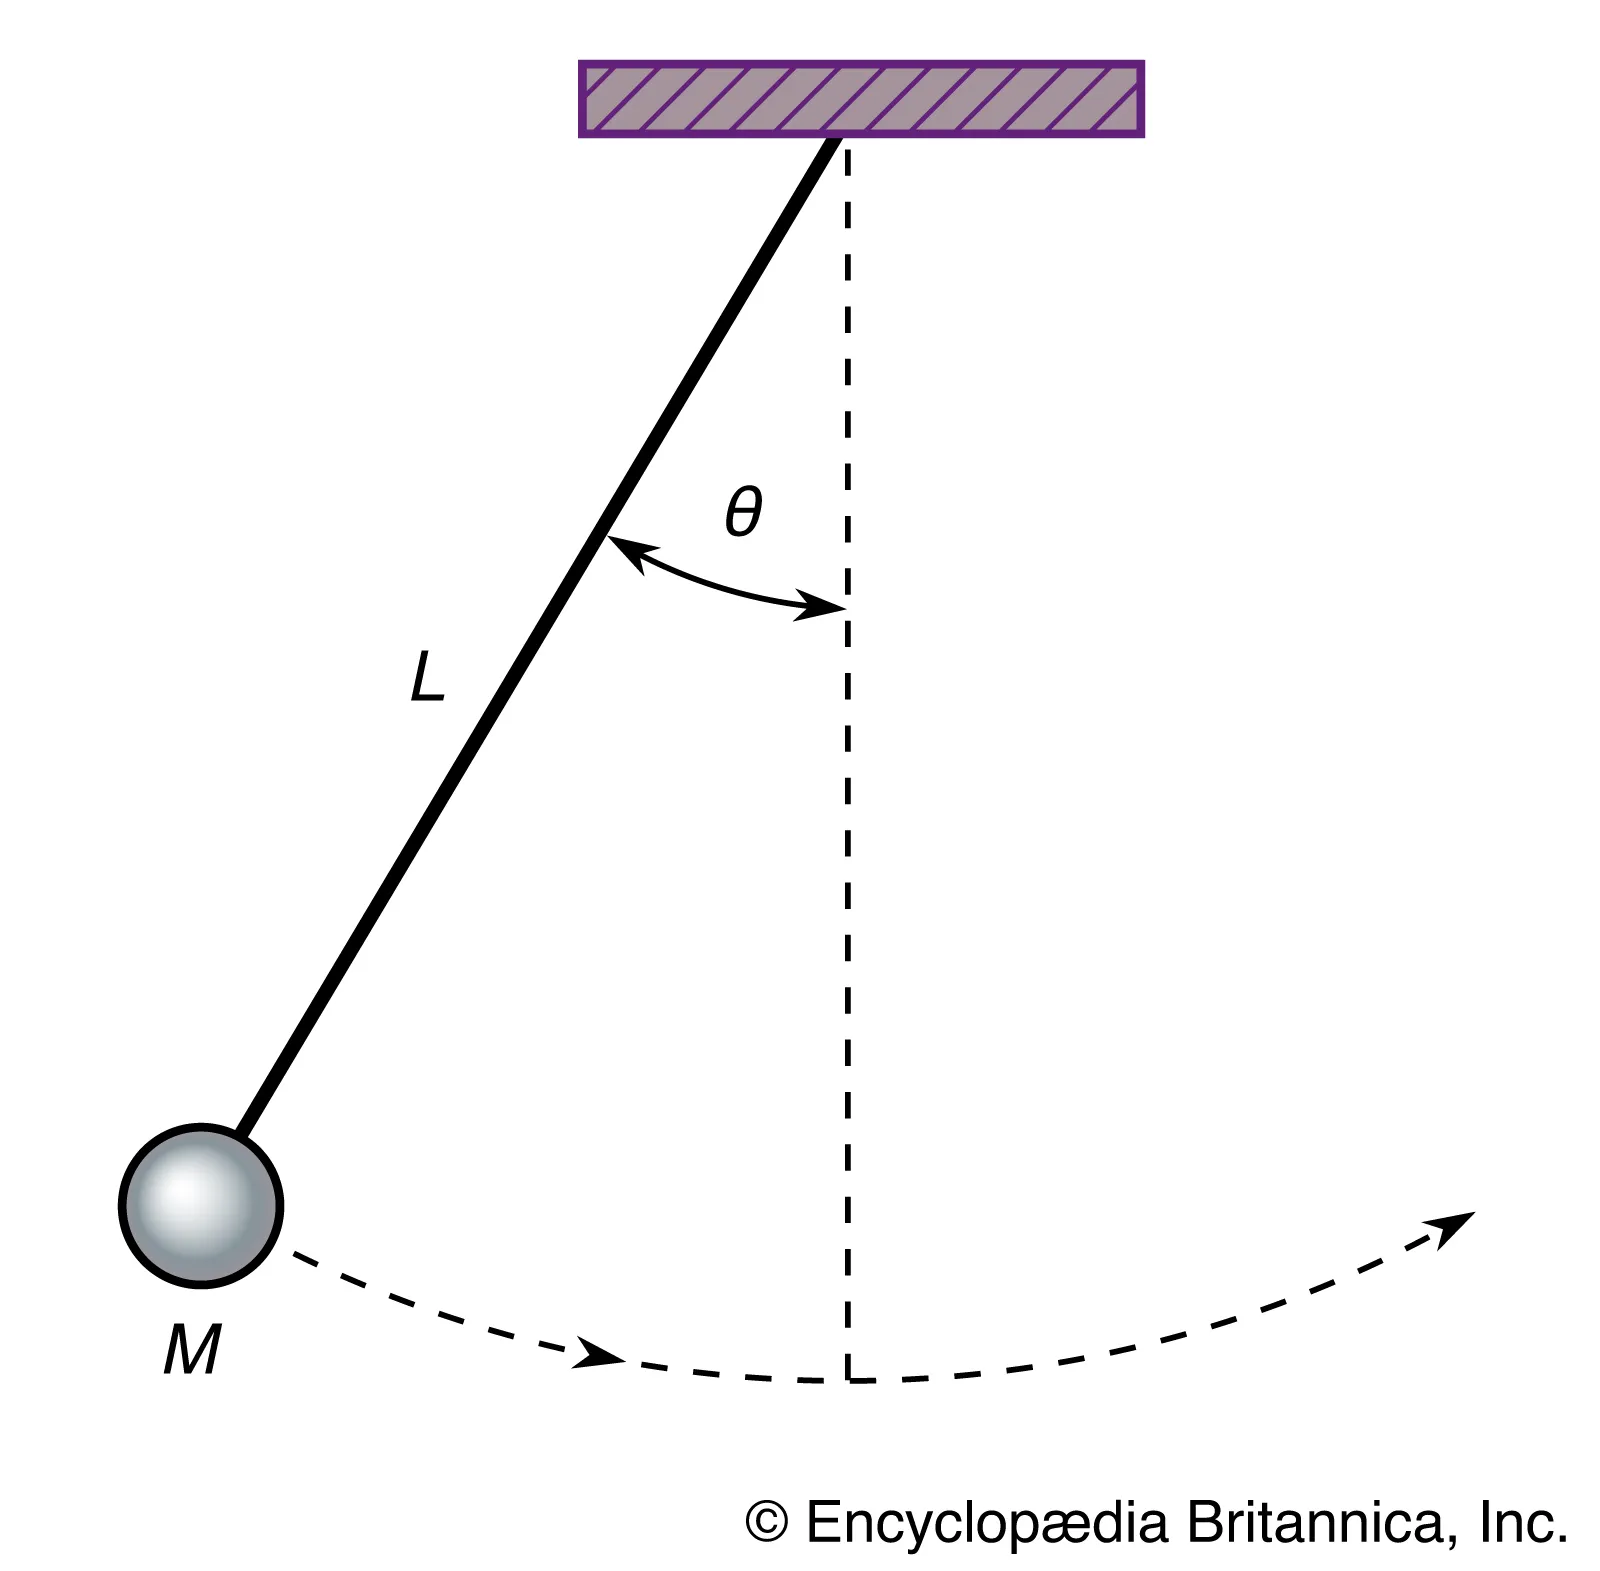

% Simple pendulum: θ̈ + (g/L)sin(θ) + (b/mL²)θ̇ = (1/mL²)τ 
% State: x = [θ; θ̇]

syms theta theta_dot tau_input real
g = 9.81;
L = 1;
b = 0.1;
m = 1;

% Nonlinear dynamics
f1_pendulum = theta_dot;
f2_pendulum = -(g/L)*sin(theta) - (b/(m*L^2))*theta_dot + (1/(m*L^2))*tau_input;

f_pendulum = [f1_pendulum; f2_pendulum];

fprintf('Pendulum nonlinear dynamics:\n');

Pendulum nonlinear dynamics:


disp(f_pendulum);

$$\left(\begin{array}{c} \dot{\theta }\\ \tau_{\mathrm{input}}-\frac{\dot{\theta }}{10}-\frac{981\,\sin\left(\theta \right)}{100} \end{array}\right)$$


$$\[
\text{Equilibrium points: } \dot{x} = 0
\]

\[
\dot{\theta} = 0, \quad
-\frac{g}{L}\sin(\theta) + \frac{1}{mL^{2}}\tau = 0
\]

\[
\text{For upright position } (\theta = 0): \quad \tau = 0
\]

\[
\text{For inverted position } (\theta = \pi): \quad \tau = 0
\]
$$



$$\[
\begin{array}{cccc}
\hline
\theta & \dot{\theta} & \tau & \text{Description} \\
\hline
0 & 0 & 0 & \text{Hanging down (stable)} \\
\pi & 0 & 0 & \text{Inverted (unstable)} \\
\hline
\end{array}
\]
$$


## Section 2.8: Jacobian Linearization

**Mathematical Background**

For nonlinear system $\dot{x} = f(x,u)$, linearization around $(x_e, u_e)$:


$$\delta\dot{x} = A\delta x + B\delta u$$


where:


$$A = \frac{\partial f}{\partial x}\bigg|_{x_e,u_e}, \quad B = \frac{\partial f}{\partial u}\bigg|_{x_e,u_e}$$


% Symbolic variables
syms theta theta_dot tau_input real

% Redefine for clarity
states = [theta; theta_dot];
inputs = tau_input;

f_pendulum = [theta_dot;
              -(g/L)*sin(theta) - (b/(m*L^2))*theta_dot + (1/(m*L^2))*tau_input];

fprintf('Computing Jacobian matrices:\n\n');

Computing Jacobian matrices:




% Jacobian with respect to states (A matrix)
A_sym = jacobian(f_pendulum, states);
fprintf('A(symbolic) = ∂f/∂x =\n');

A(symbolic) = ∂f/∂x =


disp(A_sym);

$$\left(\begin{array}{cc} 0 & 1\\ -\frac{981\,\cos\left(\theta \right)}{100} & -\frac{1}{10} \end{array}\right)$$


% Jacobian with respect to inputs (B matrix)
B_sym = jacobian(f_pendulum, inputs);
fprintf('B(symbolic) = ∂f/∂u =\n');

B(symbolic) = ∂f/∂u =


disp(B_sym);

$$\left(\begin{array}{c} 0\\ 1 \end{array}\right)$$


% Linearize around hanging down position (θ=0)
theta_e1 = 0;
theta_dot_e1 = 0;
tau_e1 = 0;

A_hang = double(subs(A_sym, {theta, theta_dot, tau_input}, {theta_e1, theta_dot_e1, tau_e1}));
B_hang = double(subs(B_sym, {theta, theta_dot, tau_input}, {theta_e1, theta_dot_e1, tau_e1}));

fprintf('\nLinearization at hanging down (θ=0):\n');


Linearization at hanging down (θ=0):


fprintf('A =\n'); disp(A_hang);

A =
         0    1.0000
   -9.8100   -0.1000



fprintf('B =\n'); disp(B_hang);

B =
     0
     1



fprintf('Eigenvalues: '); disp(eig(A_hang)');

Eigenvalues:   -0.0500 - 3.1317i  -0.0500 + 3.1317i



fprintf('System is STABLE (negative real parts)\n');

System is STABLE (negative real parts)


### Linearize around inverted position (θ=π)

theta_e2 = pi;
theta_dot_e2 = 0;
tau_e2 = 0;

A_inv = double(subs(A_sym, {theta, theta_dot, tau_input}, {theta_e2, theta_dot_e2, tau_e2}));
B_inv = double(subs(B_sym, {theta, theta_dot, tau_input}, {theta_e2, theta_dot_e2, tau_e2}));

fprintf('\nLinearization at inverted (θ=π):\n');


Linearization at inverted (θ=π):


fprintf('A =\n'); disp(A_inv);

A =
         0    1.0000
    9.8100   -0.1000



fprintf('B =\n'); disp(B_inv);

B =
     0
     1



fprintf('Eigenvalues: '); disp(eig(A_inv)');

Eigenvalues:     3.0825   -3.1825



fprintf('System is UNSTABLE (positive real part)\n');

System is UNSTABLE (positive real part)


## Section 2.9: Example - 3-State Nonlinear System Linearization

syms omega teta si u real

% Nonlinear dynamics
f1 = omega;
f2 = 39.19 - 0.2703*omega + 24.02*sin(2*teta) - 12.01*si*sin(teta);
f3 = u - 0.3222*si + 1.9*cos(teta);

f_sys = [f1; f2; f3];
states_sys = [omega; teta; si];
inputs_sys = u;

% Compute Jacobians
J_x = jacobian(f_sys, states_sys);
J_u = jacobian(f_sys, inputs_sys);

fprintf('Jacobian ∂f/∂x:\n');

Jacobian ∂f/∂x:


disp(J_x);

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{2703}{10000} & \frac{1201\,\cos\left(2\,\mathrm{teta}\right)}{25}-\frac{1201\,\mathrm{si}\,\cos\left(\mathrm{teta}\right)}{100} & -\frac{1201\,\sin\left(\mathrm{teta}\right)}{100}\\ 0 & -\frac{19\,\sin\left(\mathrm{teta}\right)}{10} & -\frac{1611}{5000} \end{array}\right)$$


fprintf('Jacobian ∂f/∂u:\n');

Jacobian ∂f/∂u:


disp(J_u);

$$\left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$


% Evaluate at specific operating point
omega_op = 0;
teta_op = 0;
si_op = 0;
u_op = 0;

A_num = double(subs(J_x, {omega, teta, si, u}, {omega_op, teta_op, si_op, u_op}));
B_num = double(subs(J_u, {omega, teta, si, u}, {omega_op, teta_op, si_op, u_op}));

fprintf('\nLinearization at (ω=0, θ=0, ξ=0, u=0):\n');


Linearization at (ω=0, θ=0, ξ=0, u=0):


fprintf('A =\n'); disp(A_num);

A =
    1.0000         0         0
   -0.2703   48.0400         0
         0         0   -0.3222



fprintf('B =\n'); disp(B_num);

B =
     0
     0
     1



### Alternative Method:

syms omega teta si u;

% Nonlinear dynamics
f1(omega, teta, si, u) = omega;
f2(omega, teta, si, u) = 39.19 - 0.2703 * omega + 24.02 * sin(2*teta) - 12.01 * si * sin(teta);
f3(omega, teta, si, u) = u - 0.3222 * si + 1.9 * cos(teta);

% Compute Jacobians
j = jacobian([f1, f2, f3], [omega, teta, si, u])

$$j(omega, teta, si, u) = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ -\frac{2703}{10000} & \frac{1201\,\cos\left(2\,\mathrm{teta}\right)}{25}-\frac{1201\,\mathrm{si}\,\cos\left(\mathrm{teta}\right)}{100} & -\frac{1201\,\sin\left(\mathrm{teta}\right)}{100} & 0\\ 0 & -\frac{19\,\sin\left(\mathrm{teta}\right)}{10} & -\frac{1611}{5000} & 1 \end{array}\right)$$



a = diff(f1, omega);
b = diff(f1, teta);
c = diff(f1, si);

d = diff(f2, omega);
e = diff(f2, teta);
f = diff(f2, si);

g = diff(f3, omega);
h = diff(f3, teta);
i = diff(f3, si);

j_u = [diff(f1, u) diff(f2, u) diff(f3, u)]'

$$j\_u(omega, teta, si, u) = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

j_x = [ a b c; d e f; g h i]

$$j\_x(omega, teta, si, u) = \left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{2703}{10000} & \frac{1201\,\cos\left(2\,\mathrm{teta}\right)}{25}-\frac{1201\,\mathrm{si}\,\cos\left(\mathrm{teta}\right)}{100} & -\frac{1201\,\sin\left(\mathrm{teta}\right)}{100}\\ 0 & -\frac{19\,\sin\left(\mathrm{teta}\right)}{10} & -\frac{1611}{5000} \end{array}\right)$$

## Section 2.10: Physical System Examples

**Example 1: DC Motor**

% DC Motor parameters
R = 1;      % Armature resistance (Ω)
L = 0.5;    % Armature inductance (H)
Kt = 0.01;  % Torque constant (N·m/A)
Kb = 0.01;  % Back-emf constant (V·s/rad)
J = 0.01;   % Moment of inertia (kg·m²)
B = 0.1;    % Viscous friction (N·m·s)

% State: x = [i; ω] (current, angular velocity)
% Input: u = V (voltage)
% Output: y = ω (angular velocity)

A_motor = [-R/L, -Kb/L;
           Kt/J, -B/J];
B_motor = [1/L; 0];
C_motor = [0, 1];
D_motor = 0;

sys_motor = ss(A_motor, B_motor, C_motor, D_motor);

fprintf('State: x = [i; ω] (current, angular velocity)\n');

State: x = [i; ω] (current, angular velocity)


fprintf('Input: V (voltage)\n');

Input: V (voltage)


fprintf('Output: ω (angular velocity)\n\n');

Output: ω (angular velocity)




fprintf('A =\n'); disp(A_motor);

A =
   -2.0000   -0.0200
    1.0000  -10.0000



fprintf('B =\n'); disp(B_motor);

B =
     2
     0



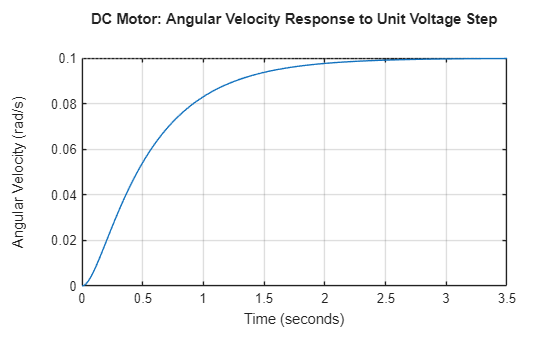


figure('Name', 'DC Motor Step Response');
step(sys_motor);
grid on;
title('DC Motor: Angular Velocity Response to Unit Voltage Step');
ylabel('Angular Velocity (rad/s)');

## Section 2.11: Summary and Key Takeaways

**Key Concepts Covered:**

- State-space representation: continuous and discrete

- System objects: `ss`, `tf`

- Conversions: `ss2tf`, `tf2ss`, `c2d`, `d2c`

- Response analysis: `step`, `impulse`, `initial`, `lsim`

- State transition: `expm`, `ode45`

- Laplace transforms: `laplace`, `ilaplace`

- Equilibrium points and linearization

- Jacobian computation: `jacobian`

- Physical system modeling examples

**MATLAB Functions Mastered:**

`ss`, `tf`, `ss2tf`, `tf2ss`, `c2d`, `d2c`, `step`, `impulse`, `initial`, `lsim`, `expm`, `ode45`, `laplace`, `ilaplace`, `jacobian`, `subs`, `stepinfo`, `residue`

**Next Steps:**

These modeling techniques enable:

- Controllability and observability analysis (Season 3)

- Stability analysis and feedback design (Season 5)

- Observer design (Season 6)